# Clustering Methods

An introduction to density-based and probabilistic clustering methods.

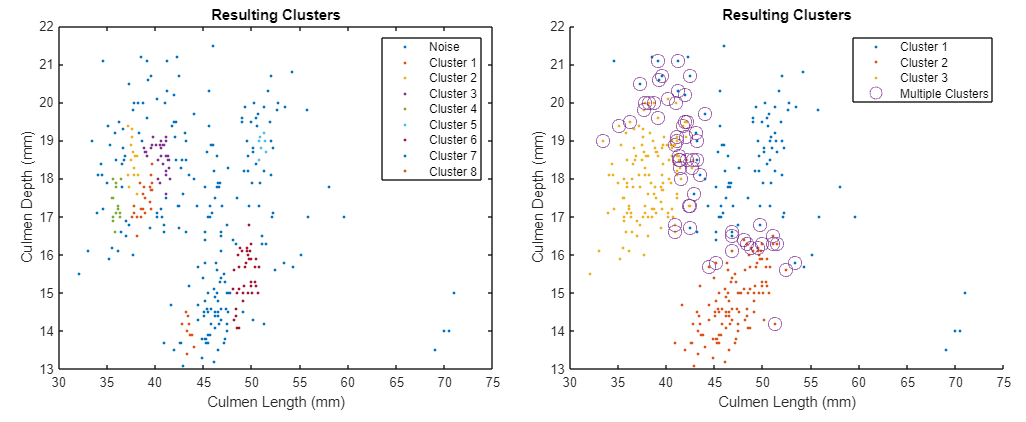

## Before you get started

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Different approaches to clustering

You've already seen that when you applied k-means to the penguin data and selected appropriate parameters, you were able to cluster the penguins by species with fairly high accuracy. However, the data did not contain any outliers. What if the data had contained measurements from a few penguins with abnormally sized beaks?

  **Try**. Use the button below to add outliers to the data.

 

warning('off','all');
Data = readtable('PenguinData.csv');
Data.Species = string(Data.Species);
DataTable = rmmissing(Data(:,[3 10 11]));
Outliers = ["Gentoo penguin (Pygoscelis papua)" 70 14; "Gentoo penguin (Pygoscelis papua)" 69 13.5; "Gentoo penguin (Pygoscelis papua)" 71 15; "Gentoo penguin (Pygoscelis papua)" 70.5 14;];
DataTable = [DataTable; array2table(Outliers, 'VariableNames',{'Species' 'CulmenLength_mm_' 'CulmenDepth_mm_'})];
CulmenData = double(table2array(DataTable(:,2:3)));
PenguinSpecies = table2array(DataTable(:,1));
shPenguinSpecies = extractBefore(PenguinSpecies," ");
Species = unique(PenguinSpecies);

rectangle('Position',[mean(CulmenData(end-3:end,1))-3 mean(CulmenData(end-3:end,2))-1.5 6 3],'Curvature',[1 1],'FaceColor','none');
text(mean(CulmenData(end-3:end,1)), mean(CulmenData(end-3:end,2))+2, "Outliers", 'HorizontalAlignment', 'center');

hold on
for idx = 1:length(Species)
    plot(CulmenData(PenguinSpecies==Species(idx),1),CulmenData(PenguinSpecies==Species(idx),2),".")
end
hold off

shSpecies = extractBefore(Species," ");
legend([shSpecies]);
xlabel("Culmen Length (mm)");
ylabel("Culmen Depth (mm)");
title("Culmen Measurements for 3 Different Types of Penguins");

% Set seed for random number generation in the next section
rng(1);

Let's run k-means again on the data now that it has outliers, using the "ideal" parameters discovered in the previous live script with random initial centroid locations, and see how it performs.

  **Try**. Use the button below to apply k-means to the data and view the results. Press the button a few times and observe how the results change based on the initial centroid locations.

** The first figure you see will be a plot of the data, color-coded by cluster. The second figure will be a heatmap depicting each data point's assigned cluster vs. its actual label. If the algorithm performs well, each row and each column of the heatmap will have exactly one high count (dark blue square). The more overlap there is between the clusters, the less accurate the algorithm was.*

CulmenLength = CulmenData(:,1);
CulmenDepth = CulmenData(:,2);
xCenters = (rand(1,3) * (max(CulmenLength) - min(CulmenLength)) + min(CulmenLength))';
yCenters = (rand(1,3) * (max(CulmenDepth) - min(CulmenDepth)) + min(CulmenDepth))';

[ClusterIndices,~] = kmeans(CulmenData, 3, 'Distance', 'cosine', 'Start', [xCenters yCenters]);

plot(CulmenData(ClusterIndices==1,1), CulmenData(ClusterIndices==1,2), '.');
FinalCentroids(1,:) = [mean(CulmenData(ClusterIndices==1,1)) mean(CulmenData(ClusterIndices==1,2))];
hold on;
for idx = 2:5
    plot(CulmenData(ClusterIndices==idx,1), CulmenData(ClusterIndices==idx,2), '.');
    FinalCentroids(idx,:) = [mean(CulmenData(ClusterIndices==idx,1)) mean(CulmenData(ClusterIndices==idx,2))];
end
LabelFinal = scatter(FinalCentroids(:,1), FinalCentroids(:,2), 100, '*', "SeriesIndex", 6);
LabelInit = scatter(xCenters, yCenters, 100, '*', "SeriesIndex", 7);
xlabel("Culmen Length (mm)");
ylabel("Culmen Depth (mm)");
title("Resulting Clusters");
legend([LabelFinal LabelInit], {'Final Centroids' 'Initial Centroids'});
hold off;

figure;
HeatmapTbl = table(ClusterIndices, shPenguinSpecies, 'VariableNames', {'Assigned Cluster', 'Species'});
heatmap(HeatmapTbl, "Species", "Assigned Cluster");

 **Reflect**. Now that the data contains outliers, what effect did you observe on the importance of the initial centroid locations? If you were working with a significantly larger data set, potentially with more clusters, would you always be able to quickly and accurately select the initial centroid locations by hand?

While k-means has its advantages, there are also situations in which a different clustering algorithm might be more appropriate. K-means is a *distance-based* clustering method; in this live script, you'll learn about two more methods of clustering: density-based methods and probabilistic methods.

### **Density-based methods**

Density-based clustering methods work by detecting *dense* areas in the data (areas where data points are particularly concentrated) and then determining where they are separated by more *sparse* areas (areas where there are less data points). This means that every data point may not be labeled as part of a cluster; data points in particularly sparse areas will be labeled as *noise *and will essentially be considered irrelevant.

 **Exercise. **See if you can identify the dense areas of the plot below! There are three dense areas, so you will have three clicks - if you correctly identify a dense area, the data points in that region will change color. Once you have made your three guesses, you'll be able to see how you did.

 

t = 2*pi*rand(100,1);
r = 2*sqrt(rand(100,1));
x = 7 + r.*cos(t);
y = 10 + r.*sin(t);
t2 = 2*pi*rand(100,1);
r2 = 1.5*sqrt(rand(100,1));
x = [x; 3 + r2.*cos(t2)];
y = [y; 3 + r2.*sin(t2)];
t3 = 2*pi*rand(100,1);
r3 = sqrt(rand(100,1));
x = [x; 8 + r3.*cos(t3)];
y = [y; 2 + r3.*sin(t3)];
x = [x; rand(100,1) * 10];
y = [y; rand(100,1) * 14];

scatter(x, y, 100, '.', "SeriesIndex", 2);
title("Find the dense areas!");

for i = 1:3
    [xGuesses, yGuesses] = ginput(1);

    check1 = (x > 5 & x < 9) & (y > 8 & y < 12);
    check2 = (x > 1.5 & x < 4.5) & (y > 1.5 & y < 4.5);
    check3 = (x > 7 & x < 9) & (y > 1 & y < 3);

    hold on;
    check1Guesses = (xGuesses > 5 & xGuesses < 9) & (yGuesses > 8 & yGuesses < 12);
    check2Guesses = (xGuesses > 1.5 & xGuesses < 4.5) & (yGuesses > 1.5 & yGuesses < 4.5);
    check3Guesses = (xGuesses > 7 & xGuesses < 9) & (yGuesses > 1 & yGuesses < 3);
    if check1Guesses
        scatter(xGuesses, yGuesses, 100, '*', "SeriesIndex", 5);
        scatter(x(check1), y(check1), 100, '.', "SeriesIndex", 5);
    elseif check2Guesses
        scatter(x(check2), y(check2), 100, '.', "SeriesIndex", 5);
        scatter(xGuesses, yGuesses, 100, '*', "SeriesIndex", 5);
    elseif check3Guesses
        scatter(x(check3), y(check3), 100, '.', "SeriesIndex", 5);
        scatter(xGuesses, yGuesses, 100, '*', "SeriesIndex", 5);
    else
        scatter(xGuesses, yGuesses, 100, '*', "SeriesIndex", 2);
    end
end
hold off;

 **Reflect**. In what ways are density-based clustering methods different from distance-based methods such as k-means?

#### **DBSCAN**

A common example of a density-based clustering algorithm is DBSCAN. DBSCAN stands for *Density-Based Spatial Clustering of Applications with Noise*. It requires two input parameters:

- **Epsilon (**`ε`**)**: The maximum distance between any two points for them to be considered part of the same cluster. Similarly to k-means, you can use a variety of distance metrics to define `ε`.

- **Minimum points (**`MinPts`**)**: The minimum number of points required to form a cluster.

In DBSCAN, there are three types of data points:

- **Core points: **Points that have at least `MinPts` points within a distance of `ε`

- **Border points: **Points that are not core points, but are within a distance of `ε` of a core point

- **Noise: **Points which are not core points or border points

 **Reflect**. Notice that DBSCAN, unlike k-means, does not require you to specify the number of clusters in advance. Why might this be advantageous? Can you think of any situations where it might be a disadvantage?

With these definitions in mind, let's see how the algorithm can be applied to a small example data set. *Make sure you work through this example in order. *

  **Try**. Use the button below to view the data:

 

xData = [1 1 2 2 3 4 4 4 1 2];
yData = [1 2 1 2 3 1 2 3 4 4];
scatter(xData, yData, 300, '.', "SeriesIndex", 1);
title("Example Data");
xlim([0 5]);
xticks([0:5]);
ylim([0 5]);
yticks(0:5);

Now, let's apply the algorithm step by step:

1. Choose the values of `ε` and `MinPts`. There are a few ways to select these values. Ultimately, trial and error can also be used to determine appropriate values for these parameters.

    *For this example, we'll be using *`ε = 1 `*and *`MinPts = 3`*.*

Epsilon = 1;
MinPts = 3; 

2. Select a random data point that has not yet been labeled and find all other data points within a distance of `ε`, which we will call "neighboring points".

      **Try**. Use the button below to visualize the results of this step:

 

SelectedPt = 1;
NeighboringInds = [];
for i = 1:length(xData)
    if pdist([xData(SelectedPt) yData(SelectedPt); xData(i) yData(i)], "euclidean") <= Epsilon
        NeighboringInds = [NeighboringInds i];
    end
end
scatter(xData, yData, 300, '.', "SeriesIndex", 1);
hold on;
scatter(xData(NeighboringInds), yData(NeighboringInds), 300, '.', "SeriesIndex", 6);
scatter(xData(SelectedPt), yData(SelectedPt), 300, '.', "SeriesIndex", 3);
title("DBSCAN Example");
xlim([0 5]);
xticks([0:5]);
ylim([0 5]);
yticks(0:5);
legend("Unreachable points", "Neighboring points", "Randomly selected point");
hold off;

3. If the number of data points found is greater than or equal to `MinPts`, that set of points is considered a cluster, and the initial randomly selected point is considered a *core point*.

    *Since this potential cluster has three points, which is equal to *`MinPts`*, it will be considered a cluster and the randomly selected point will be considered a core point.*

  **Pro-tip**. When counting neighboring points, always count the point itself! Every data point has at least one neighboring point, because it neighbors itself.

4. Check if each neighboring point is also a core point (if it has at least `MinPts` neighboring points). If it is, add its neighboring points to the cluster as well.

    *In this case, each neighboring point from the previous step is also a core point. Therefore, their neighboring points will be added to the cluster. *

  **Try**. Use the button below to visualize the results of this step:

 

CoreInds = [SelectedPt];
ToCheckInds = NeighboringInds;
NeighboringInds = [];
PossibleNeighboringInds = [];
for i = 1:length(ToCheckInds)
    NeighboringPts = 0;
    for j = 1:length(xData)
        if pdist([xData(ToCheckInds(i)) yData(ToCheckInds(i)); xData(j) yData(j)], "euclidean") <= Epsilon
            NeighboringPts = NeighboringPts + 1;
            if ToCheckInds(i) ~= j
                PossibleNeighboringInds = [PossibleNeighboringInds j];
            end
        end
    end
    if NeighboringPts >= MinPts
        CoreInds = [CoreInds ToCheckInds(i)];
        NeighboringInds = [NeighboringInds PossibleNeighboringInds];
    else
        NeighboringInds = [NeighboringInds ToCheckInds(i)];
    end
end
CoreInds = unique(CoreInds);
NeighboringInds = unique(NeighboringInds);
for k = 1:length(CoreInds)
    if ismember(CoreInds(k), NeighboringInds)
        NeighboringInds = NeighboringInds(NeighboringInds ~= CoreInds(k));
    end
end

scatter(xData, yData, 300, '.', "SeriesIndex", 1);
hold on;
scatter(xData(NeighboringInds), yData(NeighboringInds), 300, '.', "SeriesIndex", 6);
scatter(xData(CoreInds), yData(CoreInds), 300, '.', "SeriesIndex", 3);
title("DBSCAN Example");
xlim([0 5]);
xticks([0:5]);
ylim([0 5]);
yticks(0:5);
legend("Unreachable points", "Neighboring points", "Core points");
hold off;

5. Repeat step 4 until no more points can be added to the cluster.

    *We only have one neighboring point to check here. It is a core point, but has no new neighboring points, so our first cluster has been finalized! *

  **Try**. Use the button below to visualize the results of this step:

 

CoreInds = [CoreInds NeighboringInds];

scatter(xData, yData, 300, '.', "SeriesIndex", 1);
hold on;
scatter(xData(CoreInds), yData(CoreInds), 300, '.', "SeriesIndex", 3);
title("DBSCAN Example");
xlim([0 5]);
xticks([0:5]);
ylim([0 5]);
yticks(0:5);
legend("Unreachable points", "Cluster 1");
hold off;

6. Repeat steps 2-5 until every data point has either been assigned to a cluster or identified as noise.

 **Exercise. **Try doing step 6 on your own! Which of the following images matches your results?

A.    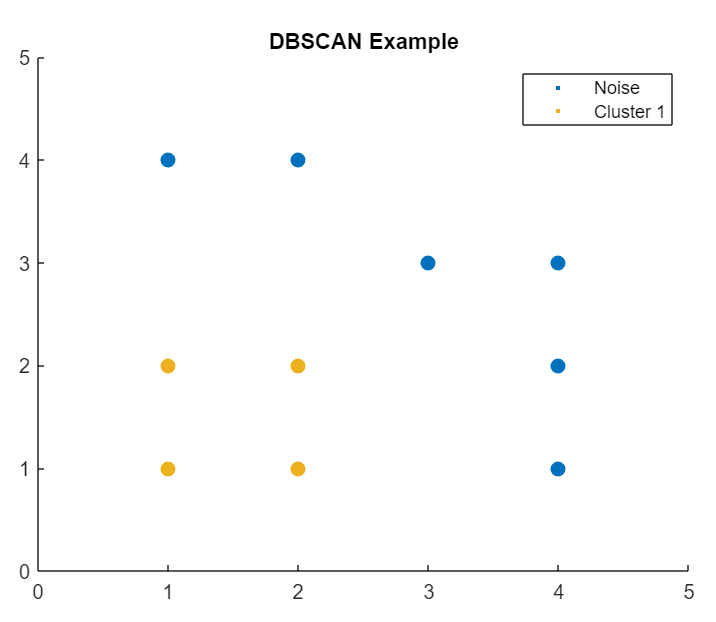           B.   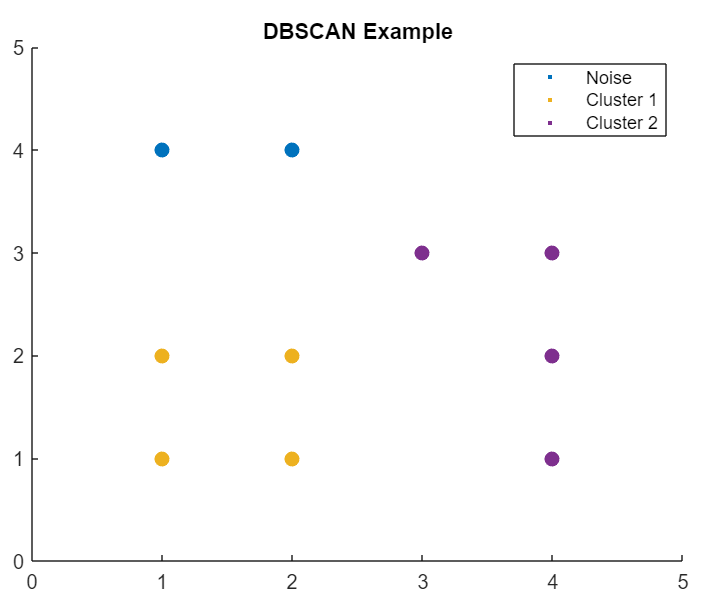

C.     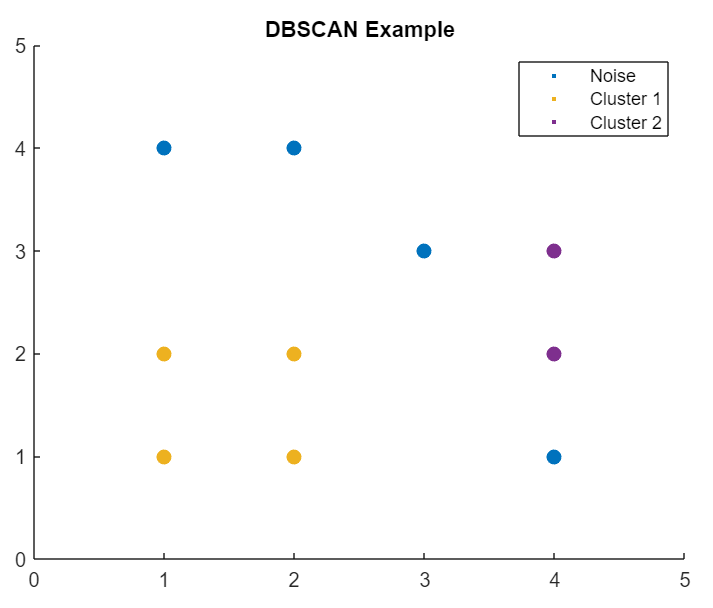          D.   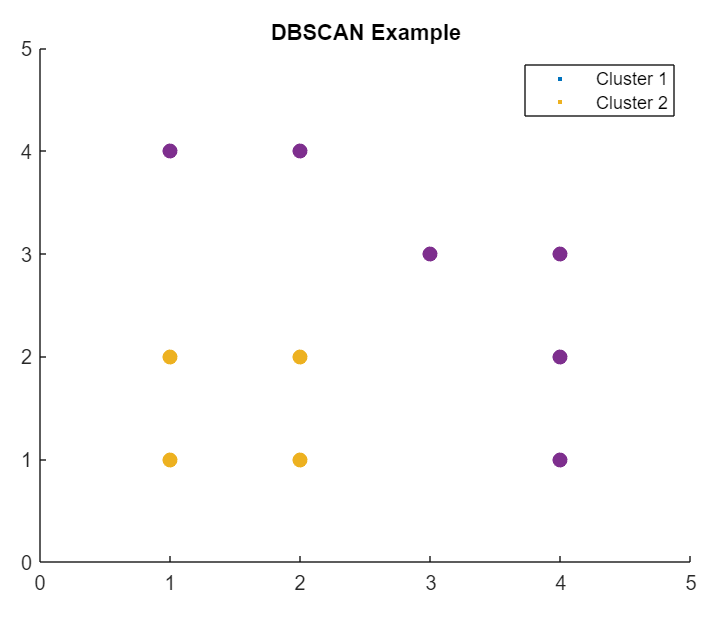

Answer = "B";
 
CheckExercise1(Answer);

7. Evaluate your results and adjust the values of `ε` and `MinPts` if necessary.

#### **Apply DBSCAN to the penguin data**

Once an outlier was added to the data set, you saw that k-means was not able to produce accurate clustering results. Since DBSCAN has the ability to ignore data points by labeling them as noise, let's see if it is able to better handle the outliers in the data.

  **Pro-tip**. In the "Count of Assigned Cluster vs. Species" visualization, the "-1" cluster contains the values that were labeled as noise.

  **Try**. Customize your DBSCAN algorithm using the following controls. Once you have set the parameters as desired, click "Run DBSCAN" to see how your algorithm performs on the data!

Epsilon = 0.6;
MinPts = 7;
 

** The first figure you see will be a plot of the data, color-coded by cluster. The second figure will be a heatmap depicting each data point's assigned cluster vs. its actual label. If the algorithm performs well, each row and each column of the heatmap will have exactly one high count (dark blue square). The more overlap there is between the clusters, the less accurate the algorithm was.*

warning('off','all');
Data = readtable('PenguinData.csv');
Data.Species = string(Data.Species);
DataTable = rmmissing(Data(:,[3 10 11]));
Outliers = ["Gentoo penguin (Pygoscelis papua)" 70 14; "Gentoo penguin (Pygoscelis papua)" 69 13.5; "Gentoo penguin (Pygoscelis papua)" 71 15; "Gentoo penguin (Pygoscelis papua)" 70.5 14;];
DataTable = [DataTable; array2table(Outliers, 'VariableNames',{'Species' 'CulmenLength_mm_' 'CulmenDepth_mm_'})];
CulmenData = double(table2array(DataTable(:,2:3)));

ClusterIndices = dbscan(CulmenData, Epsilon, MinPts);

plot(CulmenData(ClusterIndices==-1,1), CulmenData(ClusterIndices==-1,2), '.', 'MarkerSize', 10)
LegendLabels = ["Noise"];
hold on;
for idx = 1:length(CulmenData)
    plot(CulmenData(ClusterIndices==idx,1), CulmenData(ClusterIndices==idx,2), '.', 'MarkerSize', 10);
    LegendLabels = [LegendLabels append("Cluster ", num2str(idx))];
end
xlabel("Culmen Length (mm)");
ylabel("Culmen Depth (mm)");
title("Resulting Clusters");
legend(LegendLabels);
hold off;

figure;
HeatmapTbl = table(ClusterIndices, shPenguinSpecies, 'VariableNames', {'Assigned Cluster', 'Species'});
heatmap(HeatmapTbl, "Species", "Assigned Cluster")

 **Reflect**. What advantages did you notice in using DBSCAN to cluster this data? What disadvantages did you notice?

### Probabilistic methods

Probabilistic clustering methods aim to partition a data set into clusters by assigning probabilities to data points belonging in each cluster. Probabilistic methods are an example of *soft clustering* in that they allow data points to have partial membership in multiple clusters. This is in stark contrast to the distance-based and density-based methods you've seen thus far, which are examples of *hard clustering* where each data point can belong to no more than one cluster.

 **Reflect**. In what situations might probabilistic clustering methods be particularly useful? Think about scenarios in which it might be helpful to allow data points to belong to multiple clusters with different probabilities, rather than assigning each data point to strictly one cluster.

#### Gaussian Mixture Models (GMMs)

One popular probabilistic clustering algorithm is expectation-maximization clustering using Gaussian Mixture Models, or *GMMs*. Before you can learn how to cluster using GMMs, you'll need to understand what a GMM is: a probabilistic model used for representing a data set as a mixture of Gaussian distributions (also called Normal distributions). If you need a refresher on Gaussian distributions, consider checking out the "Normal Distribution" section of this [live script](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Descriptive-Stats-and-Probability&project=StatsAndProb.prj&file=continuousDistributions.mlx).

GMMs assume that data points are generated from a combination of multiple Gaussian components, each representing a distinct cluster or subpopulation within the data. They are particularly characterized by the following parameters:

- **Cluster means: **The mean values of each Gaussian component.

- **Cluster covariances: **The covariance matrices describing the shape and orientation of the data points in each cluster.

- **Mixture weights: **The relative weights of each Gaussian component in the mixture. These weights represent the prevalence of each cluster in the overall data set. In other words, the greater proportion of points that are assigned to a particular cluster, the higher that cluster's weight will be.

Essentially, a GMM models the data set as a weighted sum of Gaussian distributions, where the weights determine how much each Gaussian component contributes to the overall distribution. Each individual data point is assumed to be generated by one of the Gaussian components, and the probability of a particular data point belonging to each cluster is determined by the mixture weights and the parameters of the Gaussian components.

#### Expectation-Maximization clustering using GMMs

With these definitions in mind, let's cluster the same example set we used for DBSCAN, this time using GMMs. *Again, make sure you work through this example in order. *

  **Try**. Use the button below to view the data:

 

xData = [1 1 2 2 3 4 4 4 1 2];
yData = [1 2 1 2 3 1 2 3 4 4];

figure;
scatter(xData, yData, 300, '.', "SeriesIndex", 1);
title("Example Data");
xlim([0 5]);
xticks([0:5]);
ylim([0 5]);
yticks(0:5);

Clustering with GMMs involves estimating the parameters of a mixture of Gaussian distributions to partition the data into clusters. Let's apply the algorithm step by step:

1. Choose the desired number of clusters.

    *For this example, we'll start with 2 clusters.*

2. Randomly initialize the GMM parameters (means, covariances, and mixture weights).

    *We'll denote each parameter using its name followed by the cluster it represents (parameters ending in "1" represent cluster1, while parameters ending in "2" represent cluster 2). *

  **Try**. Use the button below to view the initial parameters:

 

Mean1 = [0.5 4]
Mean2 = [1 4.5]
Covariance1 = [1 0; 0 1]
Covariance2 = Covariance1
Weight1 = 0.5
Weight2 = 0.5

3. **Expectation step (E-step):** Calculate the probability of each data point belonging to each cluster. Work through this section to see an example of how these probabilities are calculated.

    *This step will assign each point a probability of belonging in each cluster. To visualize this, each point will be labeled with a number which corresponds to the probability of that point belonging to its assigned cluster.*

  **Try**. Use the button below to visualize the results of this step:

 

figure;
hold on;

Clust1 = [];
Clust2 = [];
BothClusts = [];
Texts = [];
for i = 1:length(xData)
    CurrPt = [xData(i) yData(i)];
    pClust1 = Weight1 * mvnpdf([xData(i) yData(i)], Mean1, Covariance1);
    pClust2 = Weight2 * mvnpdf([xData(i) yData(i)], Mean2, Covariance2);
    pClust1Norm = pClust1 / (pClust1 + pClust2);
    pClust2Norm = 1 - pClust1Norm;
    if pClust1 > pClust2
        Color = 3;
        Clust1 = [Clust1; CurrPt];
    elseif pClust2 > pClust1
        Color = 4;
        Clust2 = [Clust2; CurrPt];
    else
        Color = 1;
        BothClusts = [BothClusts; CurrPt];
    end
    scatter(CurrPt(1), CurrPt(2), 300, '.', "SeriesIndex", Color);
    CurrText = text(CurrPt(1), CurrPt(2), num2str(max(pClust1Norm, pClust2Norm)), "HorizontalAlignment", "center", "VerticalAlignment", "bottom");
    Texts = [Texts CurrText];
end
Clust1Center = scatter(Mean1(1), Mean1(2), 300, '*', "SeriesIndex", 3);
Clust2Center = scatter(Mean2(1), Mean2(2), 300, '*', "SeriesIndex", 4);

title("GMM Example");
xlim([0 5]);
xticks([0:5]);
ylim([0 5]);
yticks(0:5);
legend([Clust1Center, Clust2Center], "Cluster 1", "Cluster 2", 'AutoUpdate', 'off');
hold off;

To understand more about how these probabilities are calculated, let's take the point at (2,2) as an example. Use the button below to see the probability density function (PDF) value of each cluster's Gaussian distribution, evaluated at the point (2,2), multiplied by the corresponding weight:

 

WeightedPDFCluster1 = Weight1 * mvnpdf([xData(4) yData(4)], Mean1, Covariance1)
WeightedPDFCluster2 = Weight2 * mvnpdf([xData(4) yData(4)], Mean2, Covariance2)

The data point will be assigned to the cluster with the higher weighted PDF value at that point. The probability that you saw annotated on the above plot is calculated by dividing the higher of the two weighted PDF values by the total of the weighted PDF values. Use the button below to see how it was calculated for the point (2,2) in this example:

 

fprintf("Probability of belonging to assigned cluster = %.4f / (%.4f + %.4f) = %.5f", max(WeightedPDFCluster1, WeightedPDFCluster2), WeightedPDFCluster1, WeightedPDFCluster2, max(WeightedPDFCluster1, WeightedPDFCluster2) / (WeightedPDFCluster1 + WeightedPDFCluster2));

4. **Maximization step (M-step):** Update the parameters of the Gaussian components based on the probabilities obtained in the E-step. This requires re-estimating the means, covariances, and mixture weights to maximize the likelihood of the data.

    *This should feel familiar - it's very similar to k-means! The difference is that each cluster is defined not only by its mean, but also by its standard deviation and the weights assigned to it. To visualize this step, we will update the mean of each cluster on the plot, as well as print out the new values of each parameter. *

  **Try**. Use the button below to visualize the results of this step. Note that the cluster assignments and annotated probabilities will not change during this step, as they are only updated during the E-step.

 

Mean1 = [mean(Clust1(:,1)) mean(Clust1(:,2))]
Mean2 = [mean(Clust2(:,1)) mean(Clust2(:,2))]

StdClust1X = std(Clust1(:,1));
StdClust1Y = std(Clust1(:,2));
StdClust2X = std(Clust2(:,1));
StdClust2Y = std(Clust2(:,2));
if StdClust1X == 0
    StdClust1X = 0.0001;
end
if StdClust1Y == 0
    StdClust1Y = 0.0001;
end
if StdClust2X == 0
    StdClust2X = 0.0001;
end
if StdClust2Y == 0
    StdClust2Y = 0.0001;
end

Covariance1 = [StdClust1X 0; 0 StdClust1Y]
Covariance2 = [StdClust2X 0; 0 StdClust2Y]
Weight1 = size(Clust1, 1) / (size(Clust1, 1) + size(Clust2, 1))
Weight2 = 1 - Weight1

hold on;
Clust1Center.XData = Mean1(1);
Clust1Center.YData = Mean1(2);
Clust2Center.XData = Mean2(1);
Clust2Center.YData = Mean2(2);

hold off;

5. Repeat the E-step and M-step until the algorithm converges. Convergence either occurs when the change in the log-likelihood of the data falls below a specified threshold, or when the GMM parameters stabilize.

  **Try**. Use the button below to visualize the results of this step:

 

hold on;
for k = 1:3
    Clust1 = [];
    Clust2 = [];
    BothClusts = [];
    for i = 1:length(xData)
        CurrPt = [xData(i) yData(i)];
        pClust1 = Weight1 * mvnpdf([xData(i) yData(i)], Mean1, Covariance1);
        pClust2 = Weight2 * mvnpdf([xData(i) yData(i)], Mean2, Covariance2);
        pClust1Norm = pClust1 / (pClust1 + pClust2);
        pClust2Norm = 1 - pClust1Norm;
        if pClust1 > pClust2
            Clust1 = [Clust1; CurrPt];
        elseif pClust2 > pClust1
            Clust2 = [Clust2; CurrPt];
        else
            BothClusts = [BothClusts; CurrPt];
        end
        Texts(i).String = num2str(max(pClust1Norm, pClust2Norm));
    end
    if ~isempty(BothClusts)
        scatter(BothClusts(:,1), BothClusts(:,2), 300, '.', "SeriesIndex", 1);
    end
    if ~isempty(Clust1)
        scatter(Clust1(:,1), Clust1(:,2), 300, '.', "SeriesIndex", 3);
    end
    if ~isempty(Clust2)
        scatter(Clust2(:,1), Clust2(:,2), 300, '.', "SeriesIndex", 4);
    end

    drawnow;

    Mean1 = [mean(Clust1(:,1)) mean(Clust1(:,2))];
    Mean2 = [mean(Clust2(:,1)) mean(Clust2(:,2))];

    StdClust1X = std(Clust1(:,1));
    StdClust1Y = std(Clust1(:,2));
    StdClust2X = std(Clust2(:,1));
    StdClust2Y = std(Clust2(:,2));
    if StdClust1X == 0
        StdClust1X = 0.0001;
    end
    if StdClust1Y == 0
        StdClust1Y = 0.0001;
    end
    if StdClust2X == 0
        StdClust2X = 0.0001;
    end
    if StdClust2Y == 0
        StdClust2Y = 0.0001;
    end
    
    Covariance1 = [StdClust1X 0; 0 StdClust1Y];
    Covariance2 = [StdClust2X 0; 0 StdClust2Y];
    Weight1 = size(Clust1, 1) / (size(Clust1, 1) + size(Clust2, 1));
    Weight2 = 1 - Weight1;
    
    Clust1Center.XData = Mean1(1);
    Clust1Center.YData = Mean1(2);
    Clust2Center.XData = Mean2(1);
    Clust2Center.YData = Mean2(2);
    
    drawnow;
end
hold off;

6. Assign the data to clusters. For hard clustering applications, each data point can simply be assigned to the cluster with the highest posterior probability. Alternatively, for soft clustering applications, the posterior probabilities can be used to represent the degree of membership of each data point to each cluster.

 **Reflect**. You should have noticed that using GMMs gives a different result than DBSCAN does for this data set, because DBSCAN labels some points as noise. You may also notice, especially if you run through this example multiple times with different initial parameters, that it is susceptible to some of the same issues as k-means. Now that you've seen all three of these clustering methods in action, create a list of the pros and cons of each algorithm.

#### Apply GMMs to the penguin data

Both k-means and DBSCAN were able to cluster the penguin data relatively accurately, but each algorithm identified at least a few data points incorrectly. Let's use GMMs to apply soft clustering to the penguin data set in order to represent the uncertainty that exists in the results of this cluster analysis. The number of clusters will automatically be set to 3, based on your prior knowledge of the data.

  **Try**. Customize your GMM clustering algorithm using the following controls. Once you have set the parameters as desired, click "Cluster using GMMs" to see how your algorithm performs on the data!

MinConfidence = 0.6;
 

** The first figure you see will be a plot of the data, color-coded by cluster. The second figure will be a heatmap depicting each data point's assigned cluster vs. its actual label. If the algorithm performs well, each row and each column of the heatmap will have exactly one high count (dark blue square). The more overlap there is between the clusters, the less accurate the algorithm was.*

GMM = fitgmdist(CulmenData, 3);
p = posterior(GMM, CulmenData);
ClusterIndices = cluster(GMM, CulmenData);

Threshold = [1-MinConfidence MinConfidence];
idx = cluster(GMM, CulmenData);
idxMultiple = [];
for i = 1:3
    idxMultiple = [idxMultiple; (find(p(:,i)>=Threshold(1) & p(:,i)<=Threshold(2)))];
end

figure;
hold on
for idx = 1:3
    plot(CulmenData(ClusterIndices==idx,1), CulmenData(ClusterIndices==idx,2), '.')
end
plot(CulmenData(idxMultiple,1), CulmenData(idxMultiple,2),'o','MarkerSize',10)
legend({'Cluster 1','Cluster 2','Cluster 3','Multiple Clusters'},'Location','NorthEast')
title('Scatter Plot - GMM with Full Unshared Covariances')
xlabel("Culmen Length (mm)");
ylabel("Culmen Depth (mm)");
title("Resulting Clusters");
hold off;

figure;
ClusterIndices(idxMultiple) = [];
shPenguinSpecies(idxMultiple) = [];
HeatmapTbl = table(ClusterIndices, shPenguinSpecies, 'VariableNames', {'Assigned Cluster', 'Species'});
heatmap(HeatmapTbl, "Species", "Assigned Cluster")
title({'Count of Assigned Cluster vs. Species','(Excluding Data Points Belonging to Multiple Clusters)'})

shPenguinSpecies = extractBefore(PenguinSpecies," ");

  **Try**. You may have noticed the same issue you saw with k-means once outliers were introduced into the data. This makes sense because clustering with GMMs also relies on initial centroid locations. Use the additional slider below to try out multiple sets of initial parameters and see how the results change - the algorithm will automatically use the parameters that result in the most optimal clustering results.

MinConfidence = 0.8;
Replicates = 4;
 

GMM = fitgmdist(CulmenData, 3, 'Replicates', Replicates);
p = posterior(GMM, CulmenData);
ClusterIndices = cluster(GMM, CulmenData);

Threshold = [1-MinConfidence MinConfidence];
idx = cluster(GMM, CulmenData);
idxMultiple = [];
for i = 1:3
    idxMultiple = [idxMultiple; (find(p(:,i)>=Threshold(1) & p(:,i)<=Threshold(2)))];
end

figure;
hold on
for idx = 1:3
    plot(CulmenData(ClusterIndices==idx,1), CulmenData(ClusterIndices==idx,2), '.')
end
plot(CulmenData(idxMultiple,1), CulmenData(idxMultiple,2),'o','MarkerSize',10)
legend({'Cluster 1','Cluster 2','Cluster 3','Multiple Clusters'},'Location','NorthEast')
title('Scatter Plot - GMM with Full Unshared Covariances')
xlabel("Culmen Length (mm)");
ylabel("Culmen Depth (mm)");
title("Resulting Clusters");
hold off;

figure;
ClusterIndices(idxMultiple) = [];
shPenguinSpecies(idxMultiple) = [];
HeatmapTbl = table(ClusterIndices, shPenguinSpecies, 'VariableNames', {'Assigned Cluster', 'Species'});
heatmap(HeatmapTbl, "Species", "Assigned Cluster")
title({'Count of Assigned Cluster vs. Species','(Excluding Data Points Belonging to Multiple Clusters)'})

shPenguinSpecies = extractBefore(PenguinSpecies," ");

 **Reflect**. How did trying multiple sets of initial parameters affect the results of the clustering? Can you think of any downside to trying multiple sets of initial parameters?

## Working with unlabeled data

You may remember that clustering is typically applied to *unlabeled *data sets. This penguin data, however, is *labeled *because each data point is associated with a particular penguin species. As a result, it's been easy to determine how well your clustering algorithms are performing, since you can simply compare your results to the labels in the data set. However, you won't always have a labeled data set. In those cases, how will you know how well your algorithm is performing?

### Determining the performance of a clustering algorithm

Without labeled data, there is no way to determine if the data has been clustered "correctly", since there is no exact definition of what "correctness" would look like. However, there are still various evaluation metrics that can help determine the performance of a clustering algorithm. The choice of metric will depend on the nature of the data and goals of a given clustering task. A few common metrics are:

- **Sum of Squared Errors (SSE): **This metric simply sums the squared distances between each point and its centroid. Lower values indicate less distance between data points and their centroids, and therefore better clustering performance.

- **Silhouette Coefficient: **This metric measures how well each sample fits into its assigned cluster compared to other clusters. The Silhouette coefficient ranges from -1 to 1, where values close to 1 represent well-separated clusters, values close to -1 represent incorrect cluster assignments, and values close to 0 represent overlapping clusters.

- **Davies-Bouldin Index: **This metric measure the average similarity between clusters, taking into account both the cluster separation and compactness. Lower values indicate better-defined clusters. This metric is typically used to determine the optimal number of clusters to use for a particular clustering problem.

Let's apply each of these metrics to a random data set to see how they can be used in practice.

#### Applying performance metrics to a random data set

  **Try**. Use the button below to view the random data set, which has been clustered using k-means:

 

Data = [(randn(20,2)*0.75) + 1; (randn(20,2)*0.25) - 1];
[ClusterIndices,~,SSE] = kmeans(Data, 2);
scatter(Data(ClusterIndices==1,1), Data(ClusterIndices==1,2), 200, '.', "SeriesIndex", 3);
hold on;
scatter(Data(ClusterIndices==2,1), Data(ClusterIndices==2,2), 200, '.', "SeriesIndex", 4);
title("Random Data");
legend("Cluster 1", "Cluster 2");
hold off;

 **Exercise. **Before seeing the results, which cluster do you think will have the lower SSE?

Answer = "Cluster1";
 

CheckExercise2(Answer, SSE);

  **Try**. Now, use the button below to view the Sum of Squared Errors (SSE) for each cluster, as well as the average Silhouette coefficient for each cluster:

 

fprintf("SSE for cluster 1: %f", SSE(1));
fprintf("SSE for cluster 2: %f", SSE(2));
SilhouetteVals = silhouette(Data, ClusterIndices);
fprintf("Average Silhouette value for cluster 1: %f", sum(SilhouetteVals(ClusterIndices==1)) / length(SilhouetteVals(ClusterIndices==1)));
fprintf("Average Silhouette value for cluster 2: %f", sum(SilhouetteVals(ClusterIndices==2)) / length(SilhouetteVals(ClusterIndices==2)));

While the SSE and the Silhouette coefficient provide information about clustering performance, the Davies-Bouldin index is mainly used to determine the optimal amount of clusters for a particular data set.

  **Try**. Use the button below to view the Davies-Bouldin criterion values associated with different amounts of clusters for the above data set.

 

EvalObj = evalclusters(Data, "kmeans", "DaviesBouldin", "KList", [2 3 4]);
fprintf("Davies-Bouldin criterion for 2 clusters: %f", EvalObj.CriterionValues(1));
fprintf("Davies-Bouldin criterion for 3 clusters: %f", EvalObj.CriterionValues(2));
fprintf("Davies-Bouldin criterion for 4 clusters: %f", EvalObj.CriterionValues(3));

## 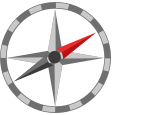Further Exploration

If you are interested, here are some additional resources to help you dive deeper into the topics covered in this live script:

- [An example of using DBSCAN to cluster Lidar data](https://www.mathworks.com/help/stats/dbscan-clustering.html)

- [An example of using GMMs to cluster Iris data](https://www.mathworks.com/help/stats/clustering-using-gaussian-mixture-models.html)

## References

- Horst AM, Hill AP, Gorman KB (2020). palmerpenguins: Palmer Archipelago (Antarctica) penguin data. R package version 0.1.0. https://allisonhorst.github.io/palmerpenguins/. doi: 10.5281/zenodo.3960218.

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

**CheckExercise1**

function CheckExercise1(Answer)
    if Answer == "B"
        disp("Great job!");
    else
        disp("Try again. If you are struggling, try drawing the problem out on paper and working through the steps by hand, labeling the data points as you go.");
    end
end

**CheckExercise2**

Copyright 2023 The MathWorks™, Inc

function CheckExercise2(Answer, SSE)
    if (SSE(1) < SSE(2) && Answer == "Cluster1") || (SSE(2) < SSE(1) && Answer == "Cluster2")
        disp("Great job!");
    else
        disp("Try again. Which cluster's values are closer to its centroid?");
    end
end